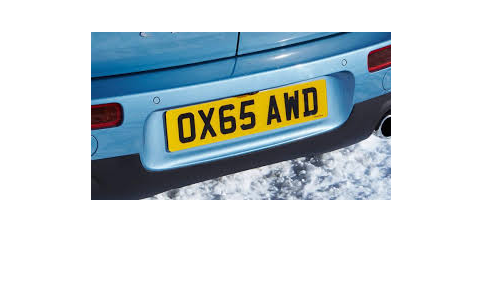

carNumber = 5;
originalImage = imread(strcat('numberplates\car', num2str(carNumber), '.jpg'));
imshow(originalImage);

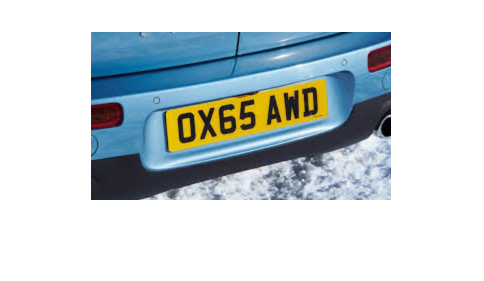


blurredImage = imgaussfilt(originalImage);
imshow(blurredImage);

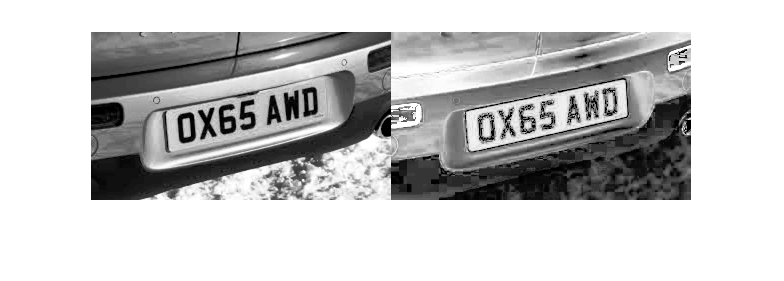

grayImage = histeq(rgb2gray(blurredImage));
grayHsvImage = histeq(rgb2gray(rgb2hsv(blurredImage)));
imshowpair(grayImage, grayHsvImage, 'montage');

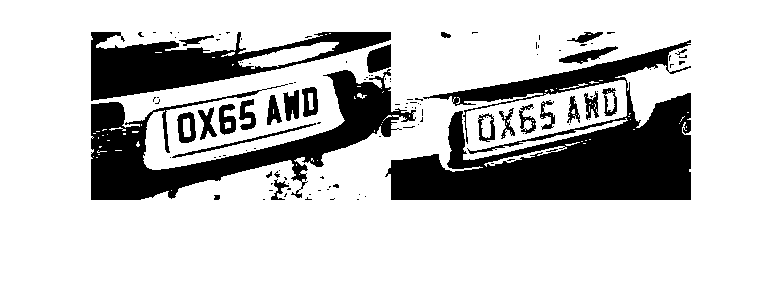

bwImage = imbinarize(grayImage);
bwHsvImage = imbinarize(grayHsvImage);
imshowpair(bwImage, bwHsvImage, 'montage');

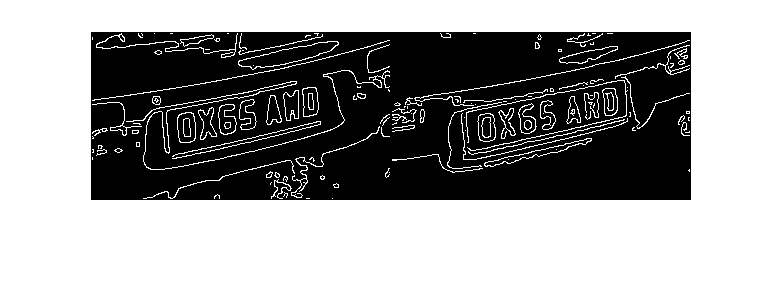

edgeImage = edge(bwImage, 'canny');
edgeHsvImage = edge(bwHsvImage, 'canny');
imshowpair(edgeImage, edgeHsvImage, 'montage');